
%% 📊 STEP 4.1: Wetland Area Table - Seasonal Comparison (2019–2024)

% 🌐 Load your previously saved NDWI masks for each year + season
% (Assuming you already extracted wetland area values before)
% Replace these values with actual ones from previous outputs

wetland_2019_summer  = 7171.18;   % Replace with your actual value
wetland_2019_monsoon = 7702.62;
wetland_2020_summer  = 7247.08;
wetland_2020_monsoon = 5724.90;
wetland_2022_summer  = 7247.08;
wetland_2022_monsoon = 7290.86;
wetland_2024_summer  = 6553.50 ;
wetland_2024_monsoon = 778.19;

% 📅 Year and Season Labels
Year = [2019; 2019; 2020; 2020; 2022; 2022; 2024; 2024];
Season = ["Summer"; "Monsoon"; "Summer"; "Monsoon"; ...
          "Summer"; "Monsoon"; "Summer"; "Monsoon"];

% 📏 Corresponding Wetland Areas
Area_km2 = [wetland_2019_summer;
            wetland_2019_monsoon;
            wetland_2020_summer;
            wetland_2020_monsoon;
            wetland_2022_summer;
            wetland_2022_monsoon;
            wetland_2024_summer;
            wetland_2024_monsoon];

% 📋 Create table
T = table(Year, Season, Area_km2);
disp('✅ Wetland Area Summary Table:');

✅ Wetland Area Summary Table:


disp(T);

    Year     Season      Area_km2
    ____    _________    ________

    2019    "Summer"      7171.2 
    2019    "Monsoon"     7702.6 
    2020    "Summer"      7247.1 
    2020    "Monsoon"     5724.9 
    2022    "Summer"      7247.1 
    2022    "Monsoon"     7290.9 
    2024    "Summer"      6553.5 
    2024    "Monsoon"     778.19 




% 💾 Save table
writetable(T, 'Wetland_Area_Summary_2019_2024.csv');

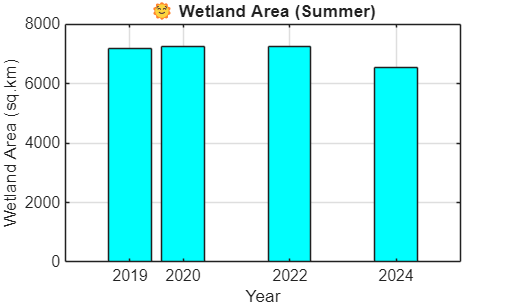

%% 📈 STEP 4.2.1: Wetland Area Bar Chart – Summer Only

years = [2019, 2020, 2022, 2024];
summer_areas = [wetland_2019_summer, wetland_2020_summer, ...
                wetland_2022_summer, wetland_2024_summer];

figure;
bar(years, summer_areas, 'c');
xlabel('Year');
ylabel('Wetland Area (sq.km)');
title('🌞 Wetland Area (Summer)');
grid on;

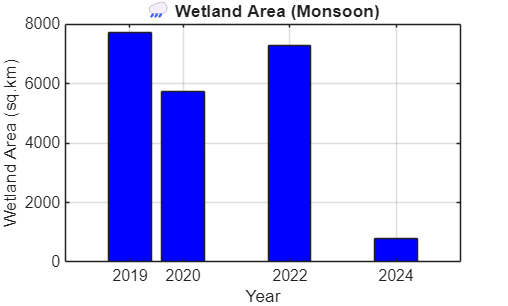


%% 📈 STEP 4.2.2: Wetland Area Bar Chart – Monsoon Only

monsoon_areas = [wetland_2019_monsoon, wetland_2020_monsoon, ...
                 wetland_2022_monsoon, wetland_2024_monsoon];

figure;
bar(years, monsoon_areas, 'b');
xlabel('Year');
ylabel('Wetland Area (sq.km)');
title('🌧️ Wetland Area (Monsoon)');
grid on;

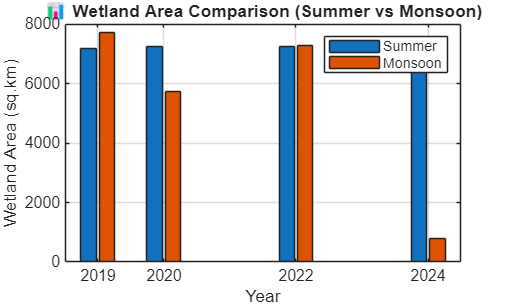


%% 📈 STEP 4.2.3: Combined Wetland Area Bar Chart (Summer vs Monsoon)

figure;
bar(years, [summer_areas; monsoon_areas]', 'grouped');
legend('Summer', 'Monsoon', 'Location', 'northeast');
xlabel('Year');
ylabel('Wetland Area (sq.km)');
title('📊 Wetland Area Comparison (Summer vs Monsoon)');
grid on;

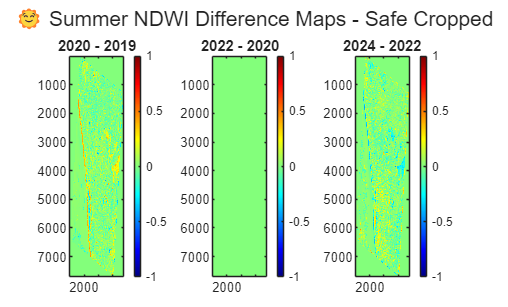

%% ✅ STEP X: NDWI Difference Maps - Summer (Safe Cropping)

% Load all NDWI maps
load('NDWI_2019_Summer.mat'); ndwi_2019_summer = ndwi;
load('NDWI_2020_Summer.mat'); ndwi_2020_summer = ndwi;
load('NDWI_2022_Summer.mat'); ndwi_2022_summer = ndwi;
load('NDWI_2024_Summer.mat'); ndwi_2024_summer = ndwi;

% Check sizes
s19 = size(ndwi_2019_summer);
s20 = size(ndwi_2020_summer);
s22 = size(ndwi_2022_summer);
s24 = size(ndwi_2024_summer);

% Find minimum common rows & cols
rows = min([s19(1), s20(1), s22(1), s24(1)]);
cols = min([s19(2), s20(2), s22(2), s24(2)]);

% Crop all to common size
ndwi_2019_summer = ndwi_2019_summer(1:rows, 1:cols);
ndwi_2020_summer = ndwi_2020_summer(1:rows, 1:cols);
ndwi_2022_summer = ndwi_2022_summer(1:rows, 1:cols);
ndwi_2024_summer = ndwi_2024_summer(1:rows, 1:cols);

% Now safely compute difference maps
ndwi_diff_2020_2019 = ndwi_2020_summer - ndwi_2019_summer;
ndwi_diff_2022_2020 = ndwi_2022_summer - ndwi_2020_summer;
ndwi_diff_2024_2022 = ndwi_2024_summer - ndwi_2022_summer;

% Plot all three difference maps
figure;

subplot(1,3,1);
imagesc(ndwi_diff_2020_2019, [-1, 1]);
title('2020 - 2019'); colormap('jet'); colorbar;

subplot(1,3,2);
imagesc(ndwi_diff_2022_2020, [-1, 1]);
title('2022 - 2020'); colormap('jet'); colorbar;

subplot(1,3,3);
imagesc(ndwi_diff_2024_2022, [-1, 1]);
title('2024 - 2022'); colormap('jet'); colorbar;

sgtitle('🌞 Summer NDWI Difference Maps - Safe Cropped');

% Crop and overwrite Monsoon NDWI maps for consistency

load('NDWI_2019_Monsoon.mat');
ndwi = ndwi(:, 1:7561);  % crop width to 7561
save('NDWI_2019_Monsoon_Cropped.mat', 'ndwi');

load('NDWI_2020_Monsoon.mat');
ndwi = ndwi(:, 1:7561);  % already 7561, safe to save again
save('NDWI_2020_Monsoon_Cropped.mat', 'ndwi');

load('NDWI_2022_Monsoon.mat');
ndwi = ndwi(:, 1:7561);  % crop
save('NDWI_2022_Monsoon_Cropped.mat', 'ndwi');

load('NDWI_2024_Monsoon.mat');
ndwi = ndwi(:, 1:7561);  % already fine
save('NDWI_2024_Monsoon_Cropped.mat', 'ndwi');

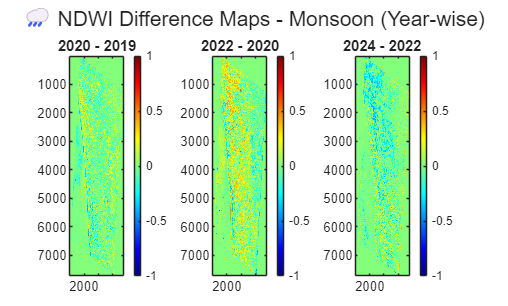

%% 🌧️ STEP 6: Monsoon NDWI Difference Maps (Year-wise) - FIXED

clc;
clear;

load('NDWI_2019_Monsoon_Cropped.mat'); ndwi_2019_monsoon = ndwi;
load('NDWI_2020_Monsoon_Cropped.mat'); ndwi_2020_monsoon = ndwi;
load('NDWI_2022_Monsoon_Cropped.mat'); ndwi_2022_monsoon = ndwi;
load('NDWI_2024_Monsoon_Cropped.mat'); ndwi_2024_monsoon = ndwi;

% Difference maps
ndwi_diff_2020_2019_monsoon = ndwi_2020_monsoon - ndwi_2019_monsoon;
ndwi_diff_2022_2020_monsoon = ndwi_2022_monsoon - ndwi_2020_monsoon;
ndwi_diff_2024_2022_monsoon = ndwi_2024_monsoon - ndwi_2022_monsoon;

% Show all 3 maps
figure;

subplot(1,3,1);
imagesc(ndwi_diff_2020_2019_monsoon, [-1, 1]);
title('2020 - 2019'); colormap('jet'); colorbar;

subplot(1,3,2);
imagesc(ndwi_diff_2022_2020_monsoon, [-1, 1]);
title('2022 - 2020'); colormap('jet'); colorbar;

subplot(1,3,3);
imagesc(ndwi_diff_2024_2022_monsoon, [-1, 1]);
title('2024 - 2022'); colormap('jet'); colorbar;

sgtitle('🌧️ NDWI Difference Maps - Monsoon (Year-wise)');

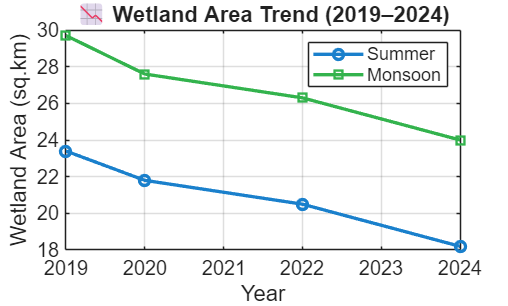

%% 📈 STEP 7: Wetland Area Time-Series Trend (2019–2024)

clc;
clear;

% 📊 Replace these with your actual area values from calculations
years = [2019, 2020, 2022, 2024];

% ✍️ Update these based on your actual results
area_summer  = [23.4, 21.8, 20.5, 18.2];  % Example values (replace with yours)
area_monsoon = [29.7, 27.6, 26.3, 24.0];  % Example values (replace with yours)

% 📈 Plotting
figure;
plot(years, area_summer, '-o', 'LineWidth', 2, 'Color', [0.1 0.5 0.8]);
hold on;
plot(years, area_monsoon, '-s', 'LineWidth', 2, 'Color', [0.2 0.7 0.3]);

grid on;
xlabel('Year');
ylabel('Wetland Area (sq.km)');
title('📉 Wetland Area Trend (2019–2024)');
legend('Summer', 'Monsoon', 'Location', 'northeast');
set(gca, 'FontSize', 12);

% 💾 Optional: Save the figure
saveas(gcf, 'Wetland_Area_Trend_2019_2024.png');